# Quadcopter Basics - Configuration and Modeling

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

In [PropellerModel](matlab:open('.\PropellerModel.mlx')), we learned how the thrust and torque generated by a propeller depend on both its physical dimensions and its rotational speed. In this script, we'll put these concepts together to understand how a quadcopter with *four* propellers works and run simple simulations to illustrate as we go along. 

For simplicity, we will assume a rigid-body dynamic model with four propellers that all produce unidirectional thrust perpendicular to the quadcopter system. Throughout this script, we compute the parameters needed to implement a moving quadcopter in Simulink in [QuadcopterMovement](matlab:open('.\QuadcopterMovement.mlx')).

## Quadcopter Coordinate System

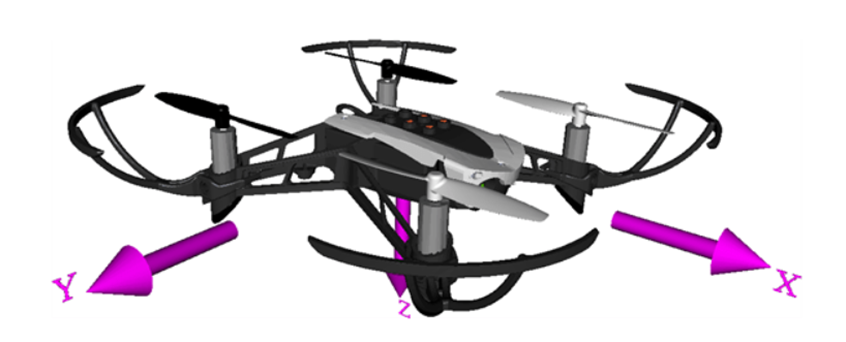

Image: [Quadcopter Physical Characteristics](https://www.mathworks.com/help/aeroblks/quadcopter-physical-characteristics.html)

Conventionally, we define the coordinate system (the body frame) for a quadcopter using the right-hand rule, with the x-axis pointing 'forward,' the y-axis pointing to the right, and the z-axis pointing downwards. 

### Propeller Configuration

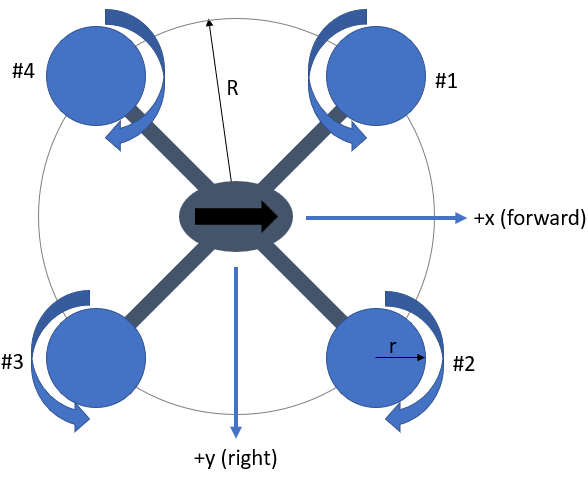             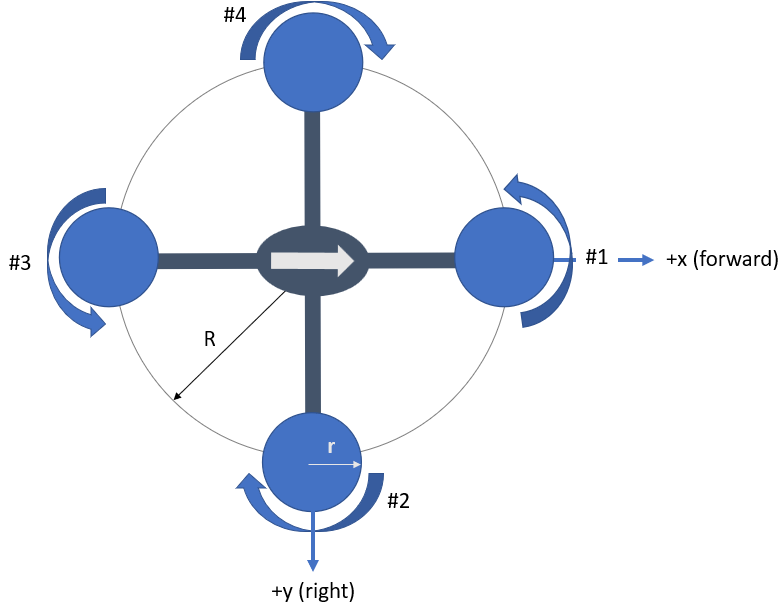

    'x' Configuration                                                                                     '+" Configuration                               

For this course, we will consider the quadcopter being operated in one of two modes:

- an 'x' configuration where the propellers are offset diagonally by 45 degrees to the direction of the quadcopter's main body.

- a '+' configuration, where the propellers are aligned along the x and y axes (or east-west/north-south). 

In each configuration, every propeller is placed at an offset of 90 degrees from the next, with its center being a distance *R *away from the body's center of mass. Each blade has a radius of *r*, and can spin at a specified angular velocity *w*. In each configuration, we set propellers 1 and 3 to spin counterclockwise (as seen from above) while propellers 2 and 4 spin clockwise. This counter-rotation will be important later. We'll call the structure connecting our four propellers the *body*.

## Motivating example

Recall how we modeled a propeller as a disk? Even a *very basic* physical model that describes a quadcopter as four such disks and a centralized body mass lets one predict:

- How arm length $R$ affects roll/pitch authority and inertia.

- How prop radius $r$ and prop mass $m$ influence attitude responsiveness.

- How propeller spin directions produce yaw torque.

- Why x-configuration drones are more common than +-configuration drones.

This is the same modeling pipeline used for early-stage controller design before adding aerodynamic drag, motor dynamics, and sensor models.

### Simple Geometric Model

We'll use a body frame with $x_B$ pointing forward, $y_B$ pointing right, and $z_B$ pointing down. As a first approximation, let's assume that the propellers are thin disks of radius $r$ meters and mass $m$ kilograms, while the body is a cuboid of length $L$ in the $x$ and $y$ directions and height $H$ in the $z$ direction. Let the mass of the body be $M_{\text{body}}$. That gives the total mass of the quadcopter as $M_{\text{quad}} = 4m+M_{\text{body}}$. Placing the origin at the center of mass of the quadcopter, and with propeller arms of length $R$ in the plane $z=0$, this positions each propeller as follows:

m = 0.07;  % propeller mass
Mbody = 1.02;                    % body mass [kg]
 
Mquad = 4*m + Mbody              % quadcopter mass 

### **Simple Inertia Model **

From the work in [Propeller Model](matlab:open('.\PropellerModel.mlx')), we know that quadcopter propellers rotate quickly. As such, it is physically reasonable to a first approximation to model each propeller as a thin solid disk of radius $r$ and mass $m$. For simplicity, we will approximate the body of the quadcopter as a cuboid with side lengths $L$ in the $x$-$y$ plane, and height $H$ in the $z$ direction. 

Recall that the moment of inertia tensor in 3D space is $I = \left[\matrix{I_{xx} & I_{xy} & I_{xz} \cr I_{yx} & I_{yy} & I_{yz} \cr I_{zx} & I_{zy} & I_{zz}}\right]$. Inertia describes how difficult (or easy) it is to change the orientation of our quadcopter, impacting flight stability, agility, and performance.

### Inertia of Propellers

About its own center (with disk normal aligned with $z_B$):

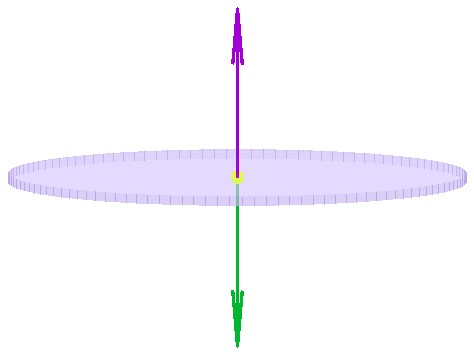         $I_{\text{disk, center}} = \left[\matrix{\frac{1}{4}mr^2 & 0 & 0 \cr 0 & \frac{1}{4}mr^2 & 0 \cr 0 & 0 & \frac{1}{2}mr^2}\right]$.

The [parallel axis theorem](https://en.wikipedia.org/wiki/Parallel_axis_theorem) states that the moment of inertia of an object with mass $m$ around an axis parallel to one through the center of mass, a distance $R$ away, adds $mR^2$ to the inertia through the center of mass. More formally, if $p$ is the vector from the center of mass of the quadcopter to the center of the respective propeller: 

$I_{\text{about CoM}} = I_{\text{center}} + m\left(||p||^2\left[\matrix{1 & 0 & 0 \cr 0 & 1 & 0 \cr 0 & 0 & 1}\right] - p^{\top}p\right)$.

For propeller 1 in the +-configuration, with $p = [\matrix{R& 0 & 0}]$, this becomes:


$$I_{\text{Prop 1 about CoM}} = \left[\matrix{\frac{1}{4}mr^2 & 0 & 0 \cr 0 & \frac{1}{4}mr^2 & 0 \cr 0 & 0 & \frac{1}{2}mr^2}\right] + m\left([\matrix{R & 0 & 0}]\cdot\left[\matrix{R \cr 0 \cr 0}\right]\left[\matrix{1 & 0 & 0 \cr 0 & 1 & 0 \cr 0 & 0 & 1}\right] - \left[\matrix{R \cr 0 \cr 0}\right]\cdot [\matrix{R & 0 & 0}]\right)$$



$$I_{\text{Prop 1 about CoM}} = \left[\matrix{\frac{1}{4}mr^2 & 0 & 0 \cr 0 & \frac{1}{4}mr^2 + mR^2 & 0 \cr 0 & 0 & \frac{1}{2}mr^2+ mR^2}\right]$$
                                                          

By symmetry, this means that for the +-configuration, 

$I_{\text{all props about CoM}} = \left[\matrix{mr^2 + 2mR^2 & 0 & 0 \cr 0 & mr^2+2mR^2 & 0 \cr 0 & 0 & 2mr^2+4mR^2}\right]$.

### Inertia of Body

The body inertia is simplest to express when the edges of the cuboid align with the $x$, $y$, and $z$ axes: in the x-configuration. 

In this case, the inertia of the body for the x-configuration is:

$I_{\text{x-body}} = \left[\matrix{\frac{M_{\text{body}}}{12}(L^2+H^2) & 0 & 0 \cr 0 & \frac{M_{\text{body}}}{12}(L^2+H^2) & 0 \cr  0 & 0 & \frac{M_{\text{body}}}{6}(L^2)}\right]$.

In the +-configuration, the body cuboid is rotated by $\theta = 45^{\circ}$ in the $x$-$y$ plane from this version. That means applying a rotation matrix of

 $R = \left[\matrix{\cos(\theta) & -\sin(\theta) & 0 \cr \sin(\theta) & \cos(\theta) & 0 \cr 0 & 0 & 1}\right] = \left[\matrix{\frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2} & 0 \cr \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} & 0 \cr 0 & 0 & 1}\right]$. 


$$I_{\text{+-body}} = RI_{\text{x-body}}R^{\top}$$


%% Mass + inertia for "+" quad (very simple)
m = 0.07;  % propeller mass   [kg]
Mbody = 1.02; % body mass [kg]
L = 0.17; % body length [m]
H = 0.06; % body height [m]
Rval = 0.13; % arm length   [m]
r = 0.12; % propeller radius [m]

if Rval <= r
    warning("You must choose Rval > r or the quadcopter isn't physically feasible.")
    Rval = r+0.01;
end

if L >= 2/sqrt(2)*Rval
    warning("Why is your body extending beyond your arms?")
end

syms R
assume(R,"real")
% propeller positions ("+")
 propPlus = [ +R,  0, 0;
    0, +R, 0;
    -R,  0, 0;
    0, -R, 0];

% propeller positions ("x")
 propX = [R/sqrt(2) -R/sqrt(2) 0;...
      R/sqrt(2) R/sqrt(2) 0; ...
      -R/sqrt(2) R/sqrt(2) 0; ...
      -R/sqrt(2) -R/sqrt(2) 0];

configuration = "+";
if configuration == "+"
    pB = double(subs( propPlus,R,Rval));
elseif configuration == "x"
    pB = double(subs( propX, R, Rval));
end

M = 4*m + Mbody;    % total mass (4 props + body)

I3 = eye(3);
I_disk_center = diag([ (1/4)*m*r^2, (1/4)*m*r^2, (1/2)*m*r^2 ]);

Iprop = zeros(3,3);
for i = 1:4
    p = pB(i,:);
    Iprop = Iprop + (I_disk_center + m*((p*p.')*I3 - (p.'*p)));
end

Ibody = diag([(1/12)*Mbody*(L^2+H^2) (1/12)*Mbody*(L^2+H^2) (1/12)*Mbody*(L^2+L^2)]);
if configuration == "+"
    theta = 45;
    RotationMatrix = [cosd(theta) -sind(theta) 0; sind(theta) cosd(theta) 0; 0 0 1];
    Ibody = RotationMatrix*Ibody*RotationMatrix.';
end

 
I = Iprop+Ibody;

disp("Total mass M [kg] =") 
disp(M)
disp("Inertia matrix I [kg*m^2] =")
disp(I)

Pulling out the individual values, this gives:

Ixx = I(1,1)
Iyy = I(2,2)
Izz = I(3,3)

 **Reflect**. What parts of this computation change as you switch between configurations?

## **Thrust and yaw-drag model**

A simple and common thrust model is quadratic in propeller speed:

- Thrust from propeller $i$: 


$$T_i = k_T \omega_i^2$$


- Reaction (drag) yaw torque from propeller $i$: 


$$Q_{z,i} = \epsilon_i k_Q \omega_i^2$$


where $k_T$ and $k_Q$ are coefficients, $\omega_i$ is the speed of rotation of the $i$th propeller, and $\epsilon_i = +1$ for counterclockwise (CCW) propellers and $-1$ for clockwise (CW) propellers.

We’ll use a standard alternating spin pattern where propellers 1 and 3 are CCW, and 2 and four are CW, as shown in the original figures:


$$\epsilon = \left[\matrix{+1 \cr -1 \cr +1 \cr -1}\right]$$


 **Reflect**. What would happen to your torque if you spun all the propellers in the same direction? What does that do to the quadcopter?

### Derive the Mixer

The mixer, $A$, is a matrix that encodes the thrust and torque generated by the rotations of each propeller. Thus, $A$ provides a mapping for a model to convert rotational speed into force.

$\left[\matrix{T\cr Q_x \cr Q_y \cr Q_z}\right] = A\left[\matrix{\omega_1 \cr \omega_2 \cr \omega_3 \cr \omega_4}\right]$.

The total thrust magnitude is


$$T = \sum_i T_i = k_T \sum_i \omega_i^2$$


Since $z_B$ is **down**, thrust points in the upward or $-z_B$ direction. Thus, 

$T_i = \left[\matrix{0 \cr 0 \cr -T_i}\right]$.

With $p_i$ denoting the vector from the center of the quadcopter to the hub of the $i$th propeller, the torque from the thrust is 


$$Q = \sum_i p_i \times T_i$$


Using $p_i = \left[\matrix{x_i \cr y_i \cr 0}\right]$, this becomes $p_i\times T_i = \left[\matrix{-y_iT_i \cr +x_iT_i\cr 0}\right]$. 

syms R k_m k_T
epsilon = [1 -1 1 -1];
pB = propX.';
A = [k_T*ones(1,4); 
    -pB(2,:)*k_T;
    pB(1,:)*k_T;
    epsilon*k_m]
syms omega_1 omega_2 omega_3 omega_4 T Q_x Q_y Q_z
omega = [omega_1^2; omega_2^2; omega_3^2; omega_4^2];
 
displayFormula("[T; Q_x; Q_y; Q_z] == A*omega")

 **Reflect**. What parts of this computation change as you switch between configurations?

### Estimate Constants

The thrust produced is modeled as a function of the propeller's angular velocity and the propeller's diameter. Under [standard modeling techniques for a quadcopter propeller](matlab:open('.\PropellerModel.mlx')), the thrust $T$ and moment $Q$ can be approximated as:


$$T_{\text{prop}} \propto \rho \omega^2 r^4 = \rho \left(\frac{N}{60}\right)^2 r^4$$



$$Q_{\text{prop}} \propto \rho\omega^2 r^5  = \rho \left(\frac{N}{60}\right)^2 r^5$$


Where $\rho$ is the air density at the given altitude, N is the angular speed of the propeller in rpm, and $r$ is the radius of the propeller. Let $M$ be the mass of the quadcopter body and $m$ be the mass of each propeller. In this case, the thrust will exactly balance the weight of the quadcopter when:

$4\cdot T_{\text{prop}} = (M+4m)\cdot g$.

Ordinarily, this requires taking some measurements of real motors and propellers. For the sake of our model, let's assume that this thrust is achieved with $N = 4000$.

g = 9.81; % m/s^2

% Quadcopter weight
W = (Mbody+m*4)*g
% for single propeller
T_prop = W/4
N = 4000 % rpm - nominal value
 

Then 

kT = T_prop/N^2

From experimental data [1], we assume a value for $k_m$ with


$$Q_{\text{z}} = k_mN^2$$


 as $k_m/k_T \approx 10^{-2}$:

km = 0.01*kT

#### Performance Curves - Torque & Moment vs Speed

This gives the performance curves of the propellers as seen below:

N = 0:1000:10000; % sweeping speed values from 0 - 10,000 rpm
T_sweep = kT * N.^2;
M_sweep = km * N.^2;
 

Plotting:

subplot(2,1,1)
plot(N, T_sweep)
xlabel('Speed (rpm)')
ylabel('Thrust (N)')
grid minor

subplot(2,1,2)
plot(N, M_sweep)
xlabel('Speed (rpm)')
ylabel('Moment (N.m)')
grid minor

These numbers will give us an easy reference for future calculations or design decisions.

## Forces and Torques

Using the assumptions we made above, let's model how the propeller forces and the propeller moments act on the quadcopter. 

 **Reflect**. What parts of this computation change as you switch between configurations?

The propellers are numbered 1 through 4, and opposite propellers (1/3 and 2/4) rotate in the same direction to cancel out their reaction moments. In a 'hover' condition, the total thrust produced by all propellers should cancel out the weight exactly, and the rotational moments should all cancel out to zero. 

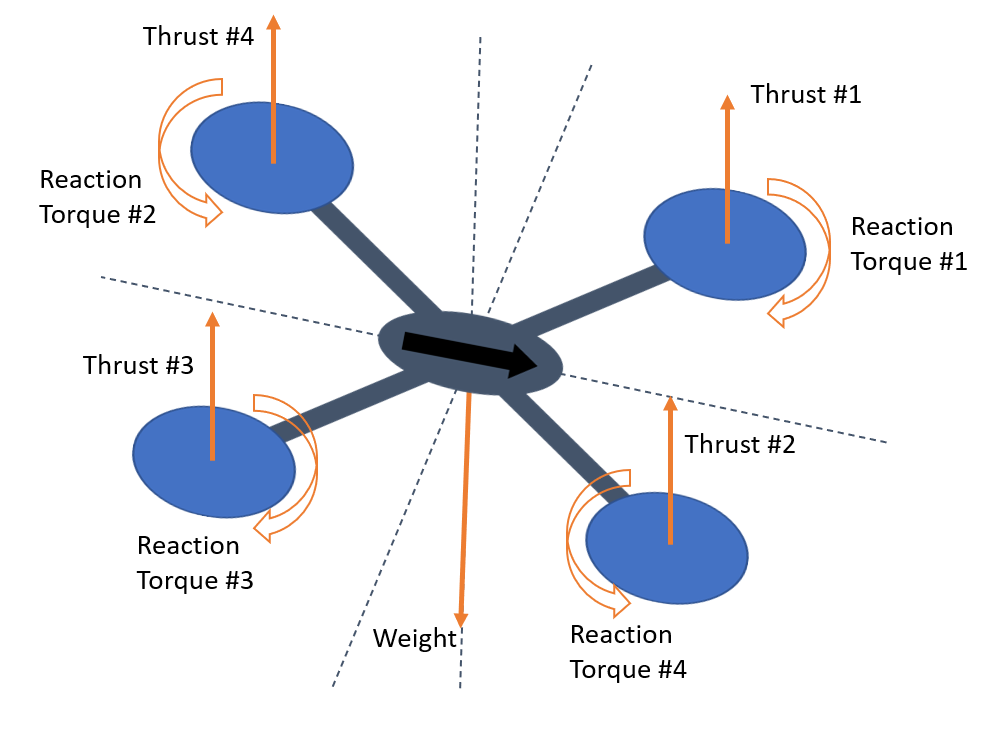

 
quad_m = double(subs(A,[k_T k_m R],[kT km Rval]))

In a steady state, where all the propellers are spinning at the nominal speed (say, 4000 rpm), all the moments cancel each other out, leaving a residual force. 

N = [4000 4000 4000 4000] 
f = quad_m*N'.^2

We can check that the total thrust force is equal to the weight of the quadcopter, as per our design. By convention, the thrust force acts in a direction opposite to the weight, thereby allowing the quadcopter to hover.

 
f(1) - W

Any change from this condition will lead to movement of one type or another, which is explained in detail in the next script: [Quadcopter Movement](matlab:open('./QuadcopterMovement.mlx'))

## Save the Parameter Values

We can also save the above parameters in the `Data` folder for reuse.

 
rootPath = currentProject().RootFolder;
if any(quad_m == 0)
    filename = "plus_quad_params.mat";
else
    filename = "x_quad_params.mat";
end
w = [0 0 0 0]; % Initial rotation speeds
fileloc = fullfile(rootPath,"Data",filename);
save(fileloc,"M","m","R","r","Ixx","Iyy","Izz","quad_m","W","kT","km","g","w")
disp("The file has been saved to " + newline + fileloc)

## Next Steps

Continue to explore the impact of changing the absolute and relative rotational speeds of propellers in [Quadcopter Movement](matlab:open('.\QuadcopterMovement.mlx')).

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## References

- Quan, Quan. *Introduction to multicopter design and control*. Singapore: Springer, 2017.